# Análisis de redes de tráfico

## Un primer problema

Las intersecciones de carretera se construyen con frecuencia como circuitos en forma de rotonda o glorieta de un solo sentido, como el que se muestra en la figura. Suponga que el tráfico debe circular en los sentidos indicados. Encuentre la solución general del flujo de red. Determine el valor más pequeño posible para `f6.`

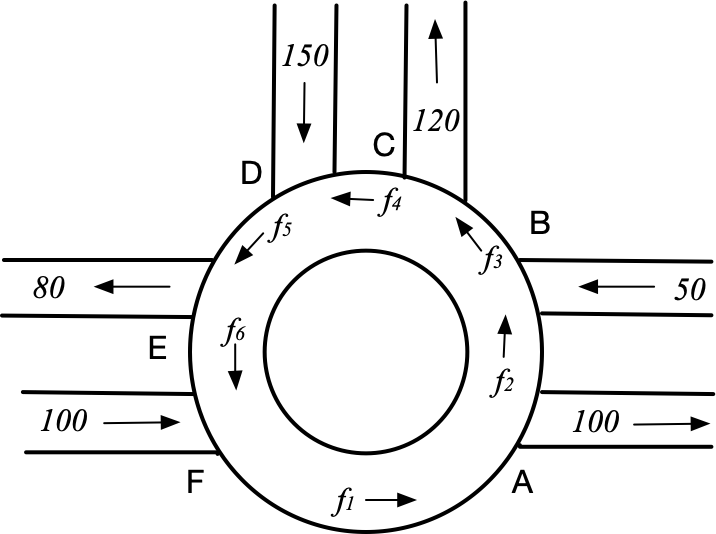

**Solución**

Para resolver el problema, primero planteamos el sistema de ecuaciones formado por las entradas y salidas de vehículos en cada nodo. Después resolveremos el sistema y analizamos los resultados.

clc, clear
syms f1 f2 f3 f4 f5 f6 t

NodoA = f1 - f2 ==  100;   
NodoB = f2 - f3 ==  -50;     
NodoC = f3 - f4 ==  120;     
NodoD = f4 - f5 == -150;  
NodoE = f5 - f6 ==   80;   
NodoF = f1 - f6 ==  100;      

ecs = [NodoA NodoB NodoC NodoD NodoE NodoF];

[A, b] = equationsToMatrix(ecs)

$$A = \left(\begin{array}{cccccc} 1 & -1 & 0 & 0 & 0 & 0\\ 0 & 1 & -1 & 0 & 0 & 0\\ 0 & 0 & 1 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 & -1 & 0\\ 0 & 0 & 0 & 0 & 1 & -1\\ 1 & 0 & 0 & 0 & 0 & -1 \end{array}\right)$$

$$b = \left(\begin{array}{c} 100\\ -50\\ 120\\ -150\\ 80\\ 100 \end{array}\right)$$


GJ = rref([A b])

$$GJ = \left(\begin{array}{ccccccc} 1 & 0 & 0 & 0 & 0 & -1 & 100\\ 0 & 1 & 0 & 0 & 0 & -1 & 0\\ 0 & 0 & 1 & 0 & 0 & -1 & 50\\ 0 & 0 & 0 & 1 & 0 & -1 & -70\\ 0 & 0 & 0 & 0 & 1 & -1 & 80\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

Tomando `f6 = t` como parámetro, las variables quedan como siguen:

f1 = t + 100;
f2 = t;
f3 = t +  50;
f4 = t -  70;
f5 = t +  80;
f6 = t;

`f6` podrá tomar como mínimo el valor 70 para que el flujo `f4 `no resulte negativo.

## Una red compleja

Hemos visto que el nodo del ejercicio anterior tiene una solución de flujo simples, pero la realidad es mucho más compleja por varias razones:

- Los problemas reales se componen de varios nodos

- Las entradas a los nodos tienen un carácter estocástico

- Cada uno de los nodos involucrados en la red ofrecen tasas de servicio diferente

- Requieren un estudio previo estadístico de acceso a las salidas de los nodos

- Pueden actuar simultáneamente semáforos con rotondas o glorietas

- El comportamiento de la red depende de otros factores, como las franjas horarias, las averías y cortes o las condiciones meteorológicas.

Todo lo anterior hace que sea imposible abordar el problema con herramientas como el álgebra lineal. Se hace necesario utilizar instrumentos más sofisticados, como es la simulación de eventos discretos, que nos permite modelar la complejidad de la red de forma más realista.

A continuación se presenta una red más sofisticada y vamos a proceder a modelarla con los elementos que hemos estudiado hasta ahora.

Sea la red representada en la siguiente figura:

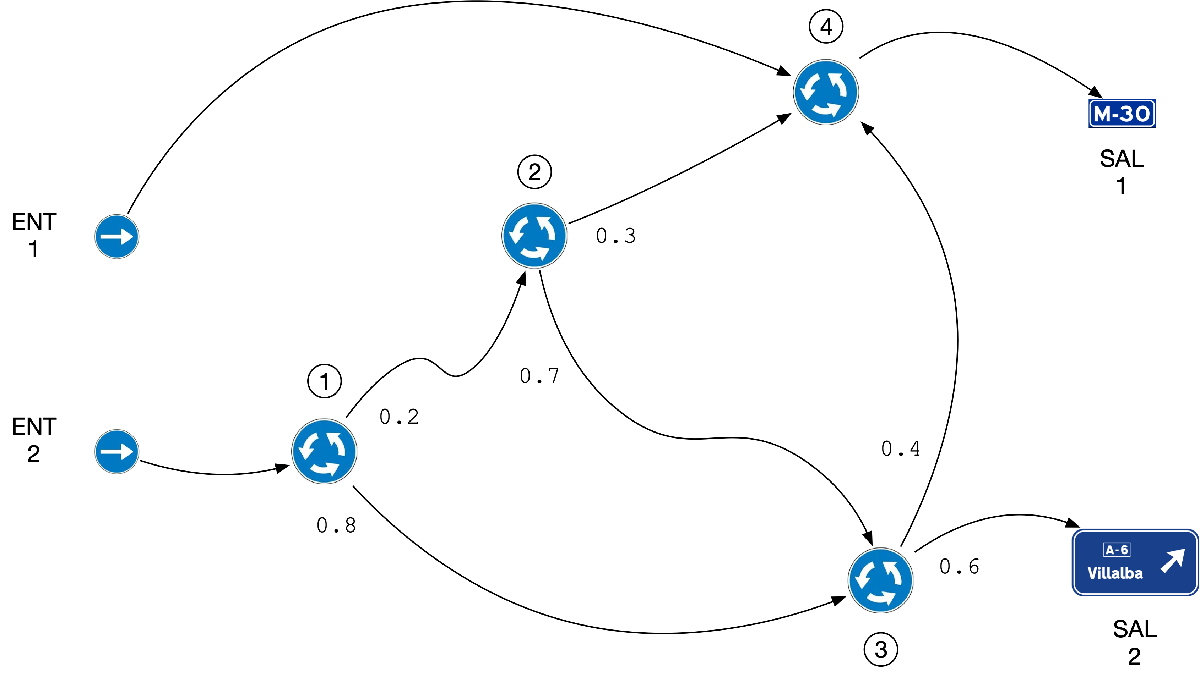

En ella identificamos un conjunto de 4 rotondas a las que se accede desde dos carreteras (ENT 1 y ENT 2) y hay dos salidas del sistema SAL 1 y SAL 2. Los números que figuran en las salidas de las rotondas corresponden a la probabilidad de que un vehículo tome esa salida. Estos datos se consiguen midiendo el tráfico durante un determinado periodo de tiempo.

Obsérvese que nada se dice del tráfico de entrada al sistema. Esto es así ya que las llegadas al sistema están reguladas por sendas distribuciones de Poisson que tendrán una tasa de llegada de `0.5` para la entrada 1 y `0.15` para la entrada 2.

Para las rotondas también se establece una tasa de servicio según una distribución de Poisson con media 1. Podría haberse utilizado una distribución uniforme, pero se considera más realista utilizar una distribución exponencial negativa.

La pregunta que nos formulamos es la siguiente: ¿hay atascos en las entradas de las rotondas? Si es así, ¿cuál sería el tiempo medio de espera en cada una de ellas?

Podríamos formularnos otras muchas preguntas (por ejemplo, ¿qué número de vehículos tomarán la salida hacia la M-30?), e incluso modificar los parámetros para estudiar situaciones concretas: podemos modificar las tasas de llegada, los rendimientos de las rotondas, las probabilidades de salida de cada una de las rotondas, cortar una de las salidas de una determinada rotonda, sustituir alguna rotonda por semáforos, etc.

Por último, para obtener unos datos lo más realistas posibles, deberemos establecer un tiempo de simulación lo suficientemente grande para visualizar la estabilidad del sistema. Se considera suficiente con un tiempo de 100.000. Si fijamos un tiempo menor, es posible que las medias no converjan y no podamos sacar conclusiones.

El modelo es el siguiente:

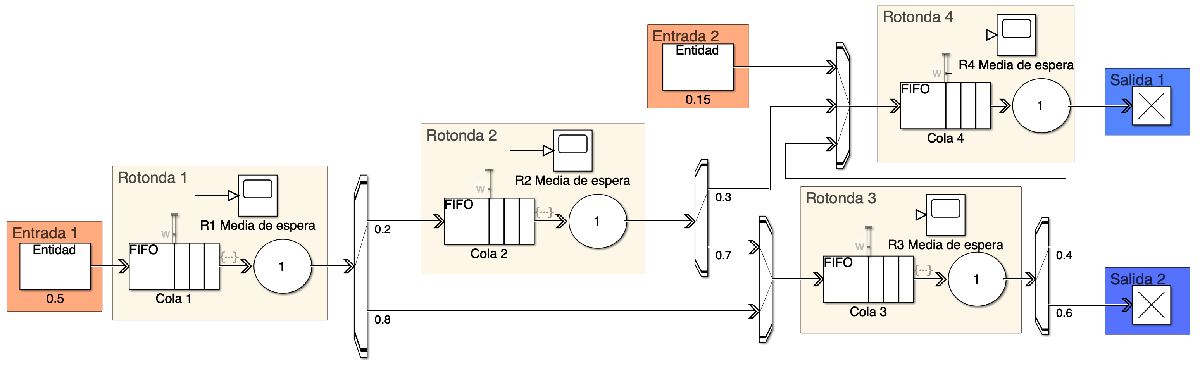

Describimos a continuación cada uno de los bloques:

**(1) Entrada 1**: Introducimos el siguiente código en **Entity generation - Intergeneration time action**:

Las cuatro primeras líneas establecen que la generación de números aleatorios sean diferentes en cada ciclo de simulación para que no se repitan resultados. Las dos últimas generan entradas aleatorias según una distribución exponencial negativa.

En la pestaña **Entity type** damos de alta un nuevo atributo que denominaremos `Ruta` y que damos el valor inicial de `0.`

En **Entity type name** cambiamos el nombre a `Entidad` o cualquier otro que resulte apropiado, teniendo en cuenta que se hará referencia a él.

**(2) Entrada 2**: Es una entrada muy similar a la anterior. Ponemos aquí los valores que deben tener sin otros comentarios:

- **Entity generation - Intergeneration time action**:

- **Entity type: **`Ruta` establecida a `1`

- **Entity type name: **`Entidad`

**(3) Cola 1, 2, 3 y 4**: En la pestaña **Statistics** seleccionamos **Average wait**. Unimos esta salida a un componente **Scope**. Los demás valores se dejan por defecto.

**(4) Servidor de Rotonda 1**: **Main - Service time source - MATLAB action**. En el campo **Service time action** introducimos el siguiente código:

En **Event action - Entry actions** se introduce el siguiente bloque de código:

Todos los demás valores se dejan por defecto.

**(5) Entity Output Switch 1**: 

- **Number of output ports** se establece a `2`. 

- **Switching criterion**: **from attribute**. 

- **Switch attribute name**: `Ruta`

**(6) Servidor de Rotonda 2:** Mismos valores que para el servidor 1, teniendo en cuenta que la variable para establecer la ruta aleatoria cambia (`Tir2`) y que la asignación de ruta con la probabilidad debe ser la adecuada a los requerimientos estadísticos de la rotonda.

**(7) Entity Output Switch 2**: 

- **Number of output ports** se establece a `2`. 

- **Switching criterion**: **from attribute**. 

- **Switch attribute name**: `Ruta`

**(8) Entity Output Switch 3**: 

- **Number of output ports** se establece a `2`. 

- **Active port selection: All**

**(9) Servidor de Rotonda 3: **Mismos comentarios que para el **Servidor de Rotonda 2**.

**(10) Entity Output Switch 5**: Mismoss comentarios que para el bloque **Entity Output Switch 2**

**(11) Entity Output Switch 4: **

- **Number of output ports** se establece a 3. 

- **Active port selection: All**

**(12) Servidor de Rotonda 4**: **Main - Service time source - MATLAB action**. En el campo **Service time action** introducimos el siguiente código:

**(13) Terminadores de SAL 1 y SAL 2: **Se dejan los valores por defecto.

Si ejecutamos la simulación, obtenemos unos valores similares a estos:

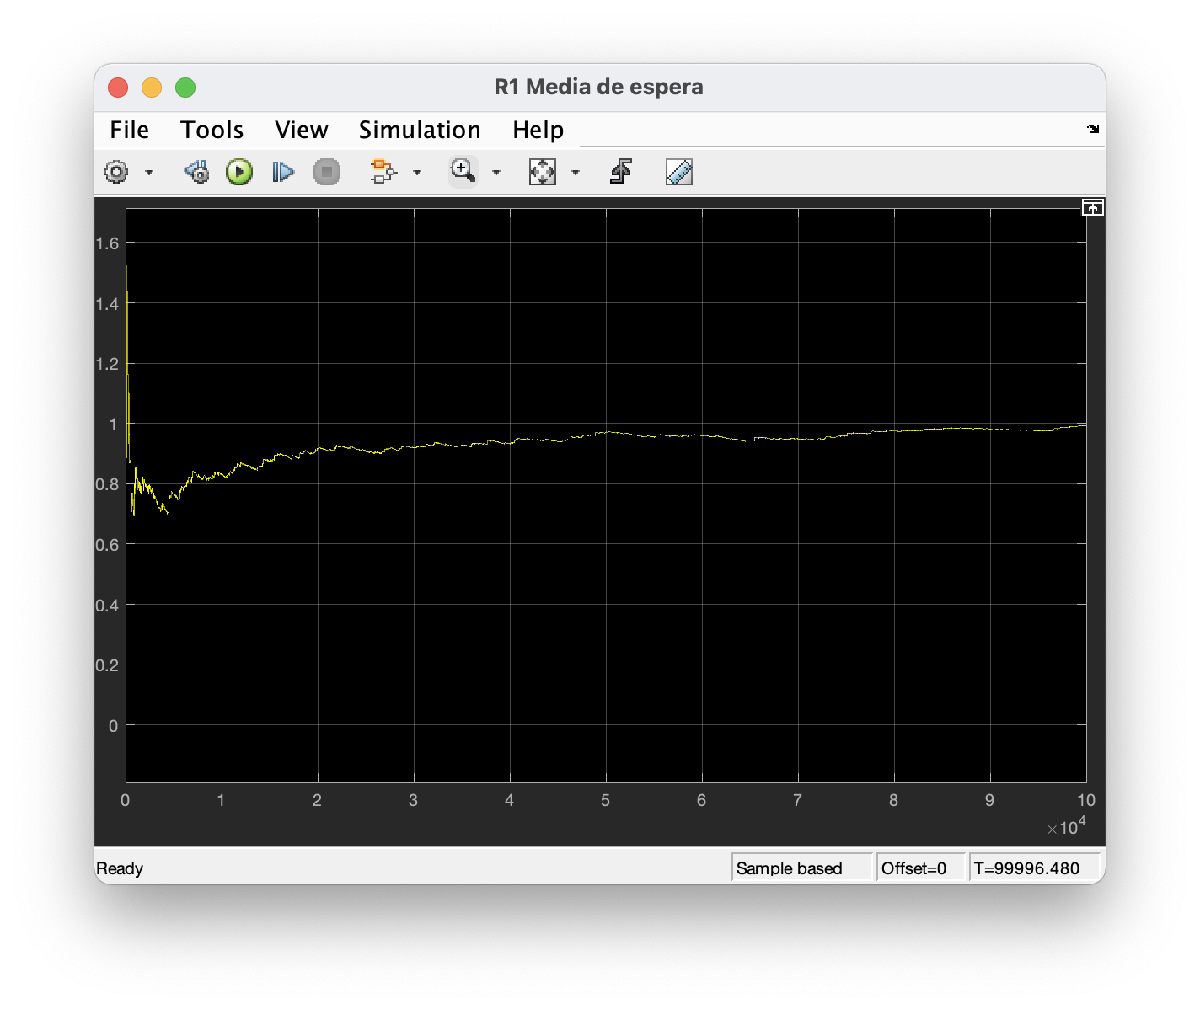

*Tiempo medio de espera en la Rotonda 1*

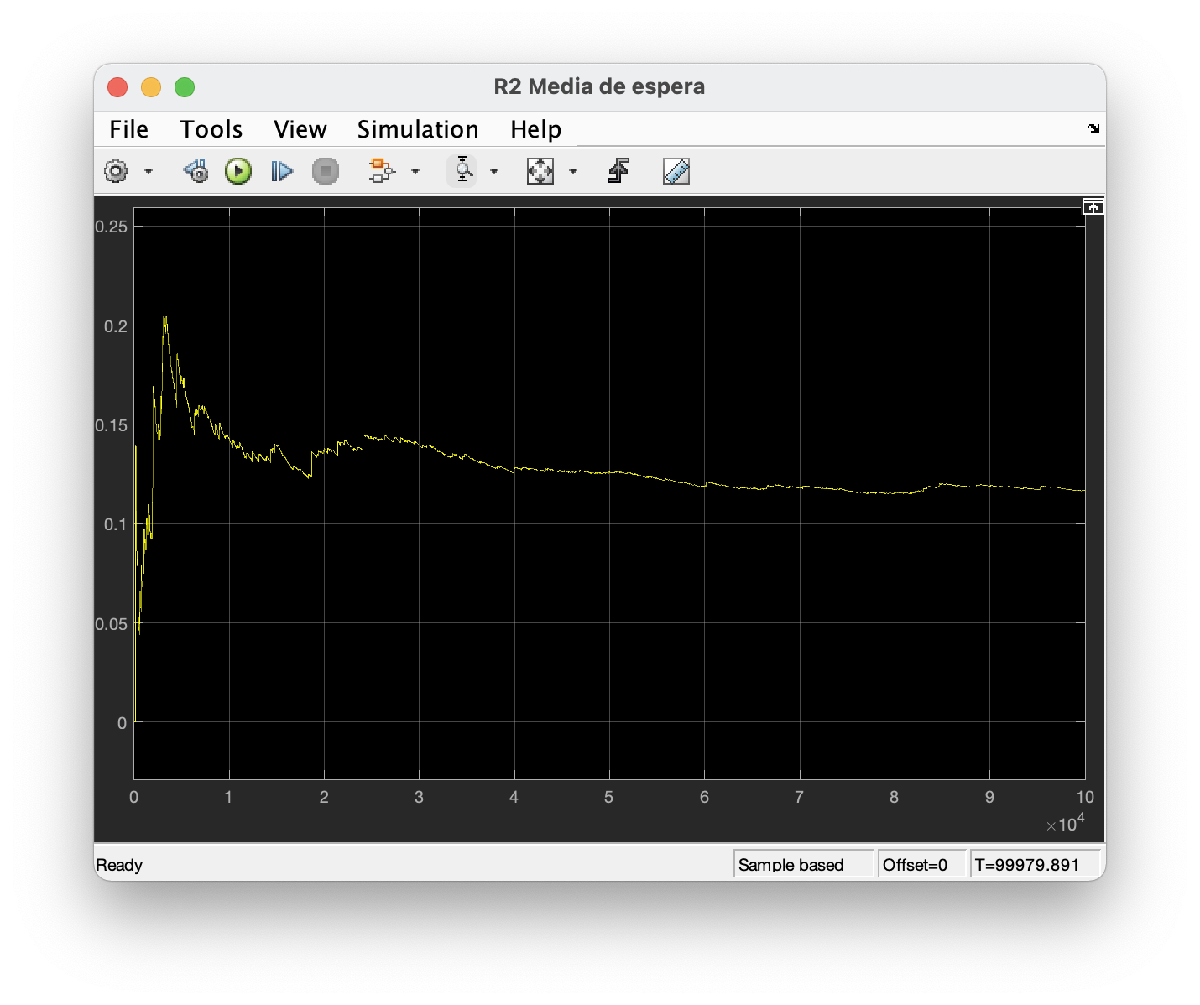

*Tiempo medio de espera en la Rotonda 2*

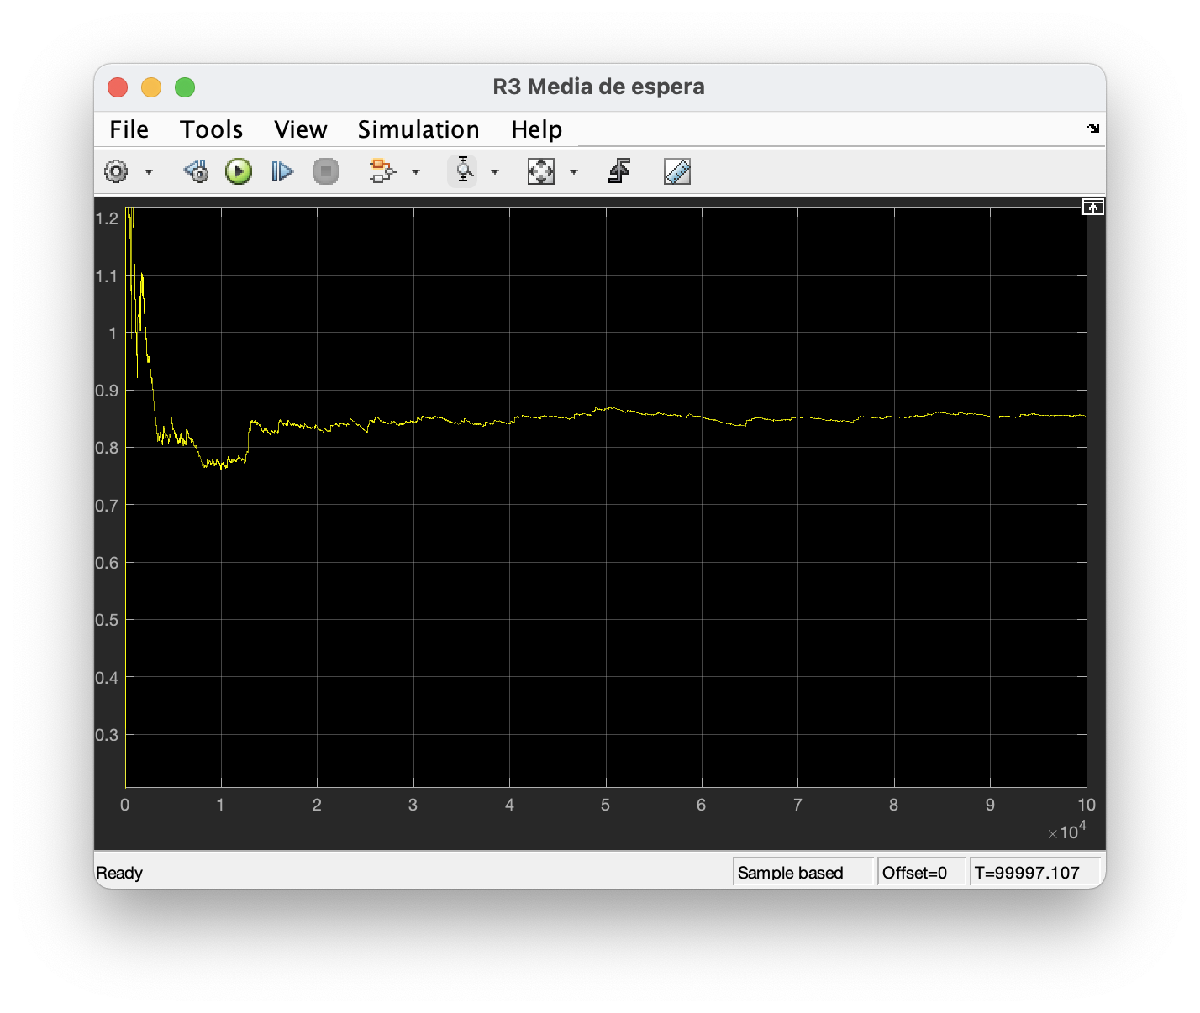

*Tiempo medio de espera en la Rotonda 3*

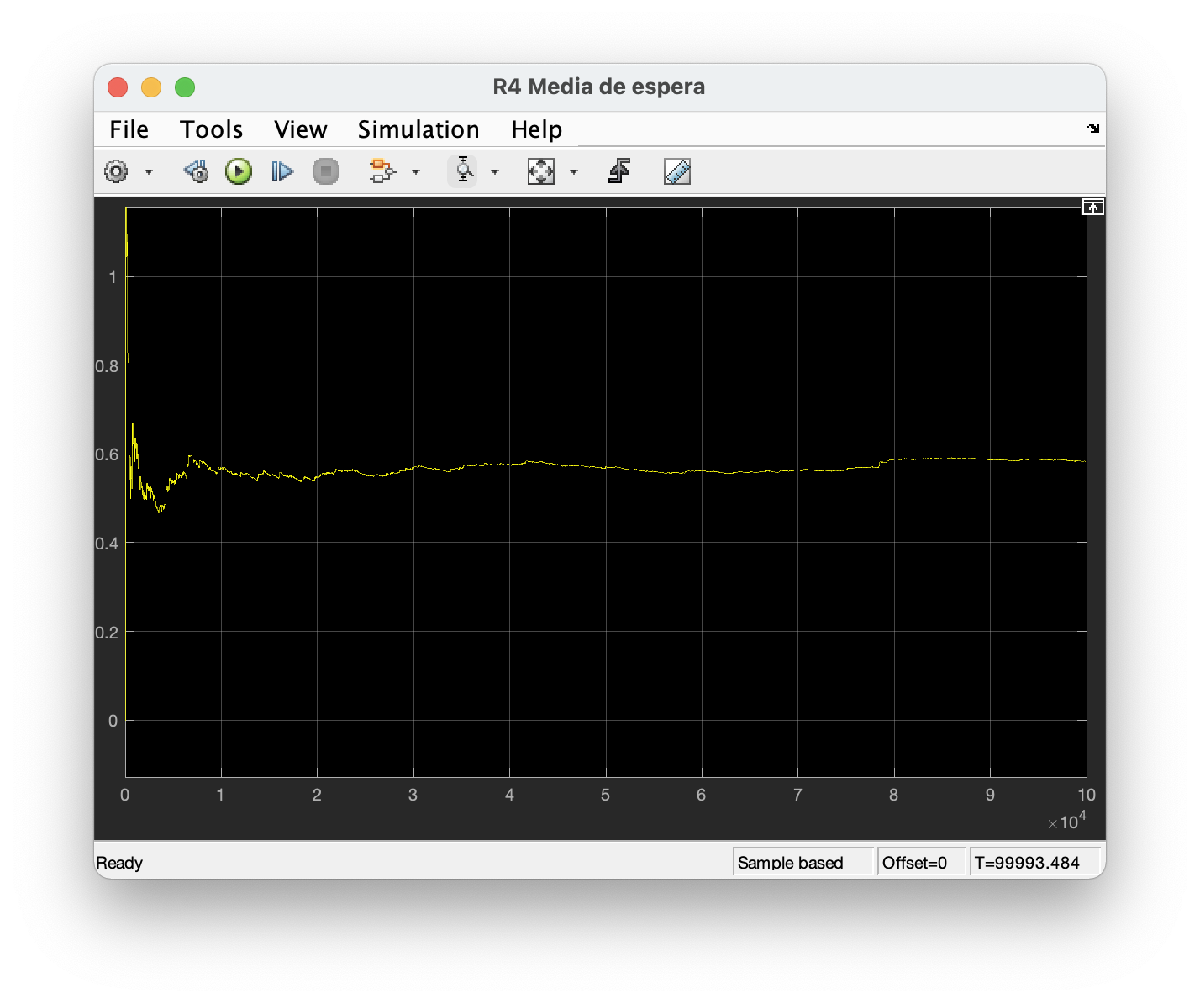

*Tiempo medio de espera en la Rotonda 4*

Podemos concluir que, con estos parámetros, en ninguna rotonda se produce un cola considerable. Es interesante el ejercicio de modificar ligeramente las tasas de llegada a ENT 1 y ENT 2 para ver cómo afectan a todo el sistema.